# Optimization and Data Analytics HW9

## An Introduction to Optimization sec. 9

## Exercise 9.1

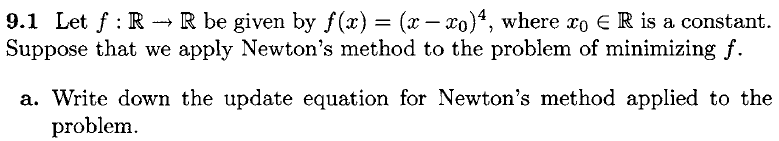

syms x0
f = @(x) (x-x0)^4;

## a)

The recursive formula representing Newton's method is defined as:


$${\mathit{\mathbf{x}}}^{\left(k+1\right)} ={\mathit{\mathbf{x}}}^{\left(k\right)} -{\mathit{\mathbf{F}}\left({\mathit{\mathbf{x}}}^{\left(k\right)} \right)}^{-1} {\mathit{\mathbf{g}}}^{\left(k\right)}$$


Where ${\mathit{\mathbf{g}}}^{\left(k\right)}$ is the gradient of *f* evaluated in the point ${\mathit{\mathbf{x}}}^{\left(k\right)}$:


$${\mathit{\mathbf{g}}}^{\left(k\right)} =\nabla f\left({\mathit{\mathbf{x}}}^{\left(k\right)} \right)$$


In order to find the update equation for Newton's method applied to the problem of minimizing *f*, it is necessary to determine the gradient and the Hessian of *f*.

The gradient is the first derivative of *f*:


$$\nabla f\left(x\right)=\frac{\text{d}}{\text{d}x}f\left(x\right)$$


syms x
Df = diff(f,x)
gradient = matlabFunction(Df)

The Hessian is the second derivative of *f:*


$$D^2 f\left(x\right)=\frac{\mathrm{d}}{\mathrm{d}x^2 }f\left(x\right)$$


D2f = diff(f,x,x)
F = matlabFunction(D2f)

The update equation is then given by:

syms x_k
g = gradient(x_k,x0)
x_new = x_k - F(x_k,x0)^-1*g

## b)

The upgrade equation from a) is rewritten as:


$${\mathit{\mathbf{x}}}^{\left(k+1\right)} ={\mathit{\mathbf{x}}}^{\left(k\right)} -\frac{{\mathit{\mathbf{x}}}^{\left(k\right)} -x_0 }{3}$$



$$3{\mathit{\mathbf{x}}}^{\left(k+1\right)} ={3\mathit{\mathbf{x}}}^{\left(k\right)} -{\mathit{\mathbf{x}}}^{\left(k\right)} -x_0 ={2\mathit{\mathbf{x}}}^{\left(k\right)} -x_0$$



$$3{\mathit{\mathbf{x}}}^{\left(k+1\right)} -x_0 ={2\mathit{\mathbf{x}}}^{\left(k\right)}$$


Adding $-2x_{0\text{ }}$ to both sides of equation:


$$3{\mathit{\mathbf{x}}}^{\left(k+1\right)} -x_0 -2x_0 ={2\mathit{\mathbf{x}}}^{\left(k\right)} -2x_0$$



$$3{\mathit{\mathbf{x}}}^{\left(k+1\right)} -3x_0 ={2\mathit{\mathbf{x}}}^{\left(k\right)} -2x_0$$



$$\frac{3{\mathit{\mathbf{x}}}^{\left(k+1\right)} -3x_0 }{3}=\frac{{2\mathit{\mathbf{x}}}^{\left(k\right)} -2x_0 }{3}$$



$${\mathit{\mathbf{x}}}^{\left(k+1\right)} -x_0 =\frac{2}{3}\left({\mathit{\mathbf{x}}}^{\left(k\right)} -x_0 \right)$$


The expression for $y^{\left(k\right)}$ may then be expressed by:


$$y^{\left(k\right)} =\left|x^{\left(k\right)} -x_0 \right|=\frac{2}{3}\left(x^{\left(k-1\right)} -x_0 \right)=\frac{2}{3}y^{\left(k-1\right)}$$


Thus, if $y^{\left(k\right)} =\frac{2}{3}y^{\left(k-1\right)}$ then $y^{\left(k+1\right)} =\frac{2}{3}y^{\left(k\right)}$.

## Exercise 9.3

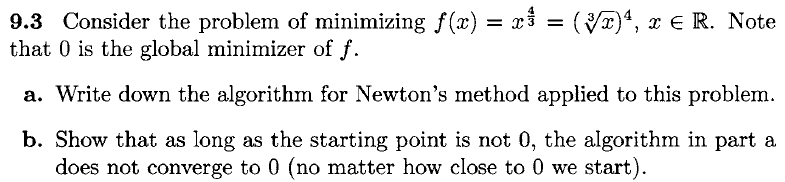

f = @(x) x^(4/3);

The recursive formula representing Newton's method is defined as:


$${\mathit{\mathbf{x}}}^{\left(k+1\right)} ={\mathit{\mathbf{x}}}^{\left(k\right)} -{\mathit{\mathbf{F}}\left({\mathit{\mathbf{x}}}^{\left(k\right)} \right)}^{-1} {\mathit{\mathbf{g}}}^{\left(k\right)}$$


Where ${\mathit{\mathbf{g}}}^{\left(k\right)}$ is the gradient of *f* evaluated in the point ${\mathit{\mathbf{x}}}^{\left(k\right)}$:


$${\mathit{\mathbf{g}}}^{\left(k\right)} =\nabla f\left({\mathit{\mathbf{x}}}^{\left(k\right)} \right)$$


In order to find the update equation for Newton's method applied to the problem of minimizing *f*, it is necessary to determine the gradient and the Hessian of *f*.

The gradient is the first derivative of *f*:


$$\nabla f\left(x\right)=\frac{\text{d}}{\text{d}x}f\left(x\right)$$


syms x
Df = diff(f,x)
gradient = matlabFunction(Df)

The Hessian is the second derivative of *f:*


$$D^2 f\left(x\right)=\frac{\mathrm{d}}{\mathrm{d}x^2 }f\left(x\right)$$


D2f = diff(f,x,x)
F = matlabFunction(D2f)

The update equation is then given by:

syms x_k
g = gradient(x_k)
x_new = x_k - F(x_k)^-1*g

## b)

From part a) it was determined that the update equation for Newton's Method is given by:


$$x^{\left(k+1\right)} =-2x^{\left(k\right)}$$


This implies that every iteration of *x* is a multiplication of the previous. The first generations are therefore given by:


$$x^{\left(1\right)} =-2x_0$$



$$x^{\left(2\right)} =-2x_1 =-2\left(-2x_0 \right)=4x_0$$



$$x^{\left(3\right)} =-2x_2 =-2\left(4x_0 \right)=-8x_0$$


This relationship with $x_0$ may then be written more generally as:


$$x^{\left(k\right)} ={\left(-2\right)}^k x_0$$


Therefore, if $x_0 \not= 0$ then the algorithm will never converge towards 0.

## Exercise 9.4

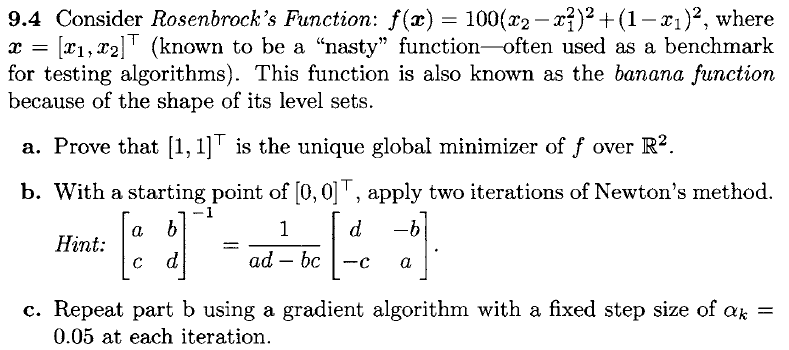

f = @(x1,x2) 100*(x2-x1^2)^2+(1-x1)^2

## a)

$f\left(x\right)$ evaluated in the point $\mathit{\mathbf{x}}={\left\lbrack 1,1\right\rbrack }^T$ is equal to zero:


$$f\left(\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack \right)=0$$


x = [1,1];
f_x = f(x(1),x(2))

From the function expression, it is apparent that $f\left(x\right)\ge 0$ for all **x**.

Hence, $f\left(x\right)>f\left(\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack \right)$ for all $\mathit{\mathbf{x}}\not= {\left\lbrack 1,1\right\rbrack }^T$, which implies that ${\left\lbrack 1,1\right\rbrack }^T$ is the global minimizer.

## b)

x0 = [0 0]

The recursive formula representing Newton's method is defined as:


$${\mathit{\mathbf{x}}}^{\left(k+1\right)} ={\mathit{\mathbf{x}}}^{\left(k\right)} -{\mathit{\mathbf{F}}\left({\mathit{\mathbf{x}}}^{\left(k\right)} \right)}^{-1} {\mathit{\mathbf{g}}}^{\left(k\right)}$$


syms x1 x2
Df = [diff(f,x1); diff(f,x2)]
gradient = matlabFunction(Df)
D2f = [diff(f,x1,x1) diff(f,x1,x2);
       diff(f,x2,x1) diff(f,x2,x2)]
F = matlabFunction(D2f)

Applying two iterations of Newton's method:

N = 2 % iterations
x = zeros(1,N)
x(1,:) = x0;

for i=1:N
    g = gradient(x(i,1),x(i,2));
    x(i+1,:) = x(i,:)'-F(x(i,1),x(i,2))^-1*g;
end
x

Two iterations was enough for Newton's method to converge to the global minimum. However, this is not likely to occur often, as the convergence speed of the algorithm depends on the objective function and the starting point.

## c)

ak = 0.05;

The update equation for the gradient algorithm is given by:


$${\mathit{\mathbf{x}}}^{\left(k+1\right)} ={\mathit{\mathbf{x}}}^{\left(k\right)} -\alpha_k \nabla f\left({\mathit{\mathbf{x}}}^{\left(k\right)} \right)$$


Applying two iterations of the gradient algorithm:

N = 2 % iterations
x = zeros(1,N)
x(1,:) = x0;

for i=1:N
    x(i+1,:) = x(i,:)'-ak*gradient(x(i,1),x(i,2));
end
x
